Pregunta 1

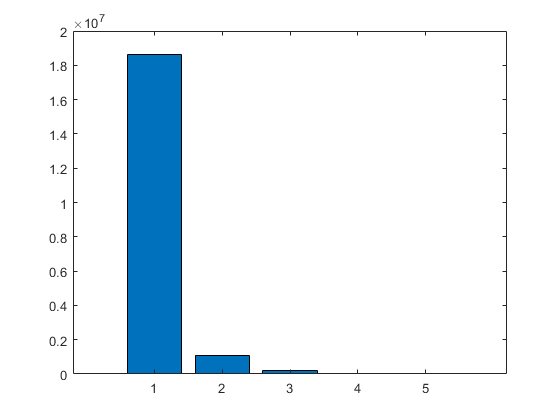

n = 5;          % Indica el número de bins (niveles de gris)
I = rgb2gray(imread('_MG_7735.JPG'));
h = imhist(I,n);
bar(h);

Pregunta 2

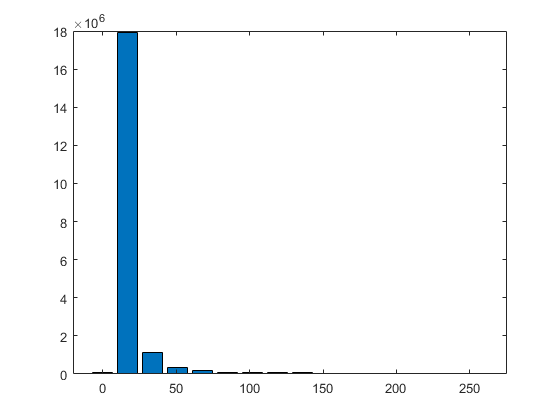

[H,intervals] = imhist(I,16);
bar(intervals,H)

Pregunta 3

M = [1 2 3; 4 5 6; 7 8 9];
N = arrayfun(@(x) 2*x,M);
max(N)

ans =     14    16    18


Pregunta 4

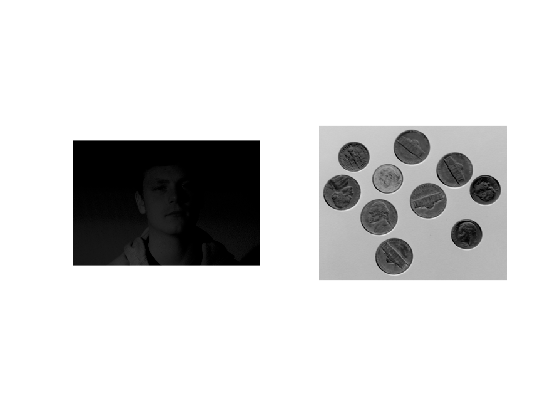

I = imread('coins.png');
N = arrayfun(@(x) 255 - x,I);
imshow(N)

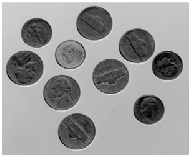

Pregunta 5

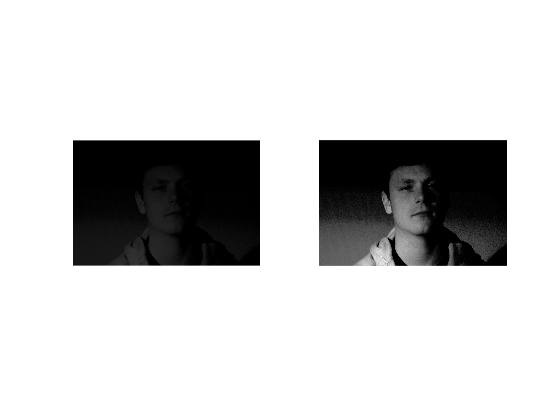

I = rgb2gray(imread('bad_lighting.jpg'));
figure
subplot(1,2,1) 
imshow(I);
I = double(I) / double(max(max(I)));
N = arrayfun(@(x) sqrt(x),I);
hold on
subplot(1,2,2) 
imshow(N)
hold off

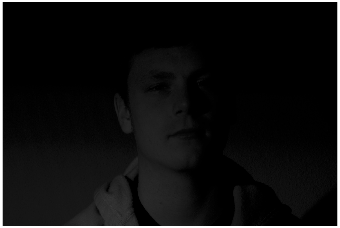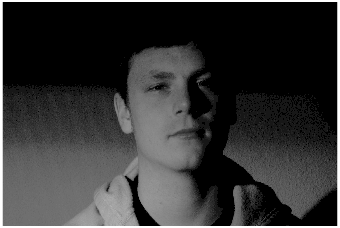

                                          a)                                                                                       b)    

Pregunta 6

Pregunta 7

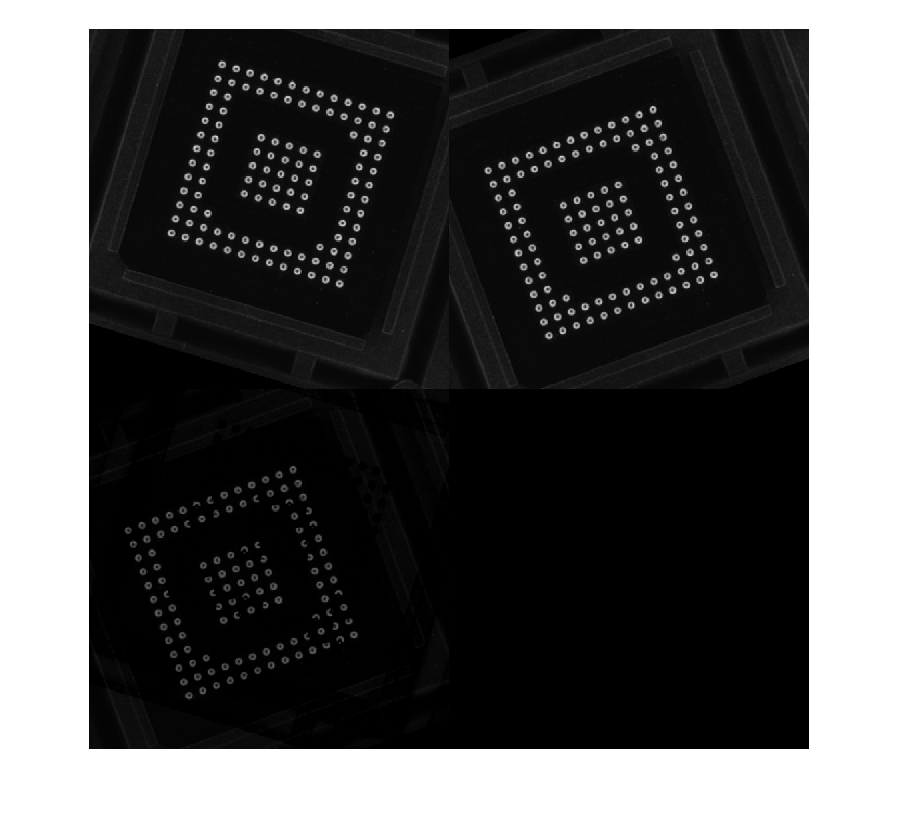

figure
A = imread("BGA116 1.tif");
B = imread("BGA116 2.tif");
C = (B - A)/2;
montage({A, B, C})

Pregunta 8

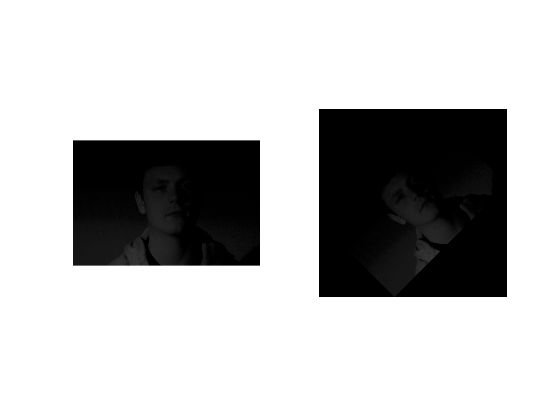

figure
I = rgb2gray(imread('bad_lighting.jpg'));
figure
subplot(1,2,1);
imshow(I);
xform = [  0.5253219   -0.5253219  0
                0.5253219   0.5253219  0
                0                 0                 1 ];

tform = affine2d(xform);
J = imwarp(I,tform);
subplot(1,2,2);
imshow(J);

Pregunta 9

close all
A = rgb2gray(imread('hand.bmp'));
figure
subplot(1,2,1);
imshow(A);
[f,c] = size(A);
columna = (f:-1:1)';
C = repmat(columna,1,c);
B = double(A).*double(C);
subplot(1,2,2);
imshow(B,[]);

Pregunta 10

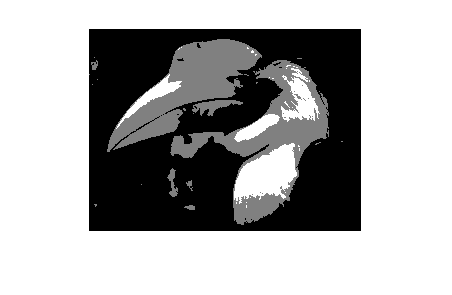

figure
I = uint8(imread("donde_esta_el_conejito.bmp")) / 127.5;
n = max(max(I));
I = I * 127.5;
imshow(I)